clc
close all
clear all
cla
rootfolder = '../../exp/tartanair_full_semantic/';
use_icp = true

use_icp = logical
   1


gtfilename_cvo = append(rootfolder,'cvo_error_list.txt');
error_cvo = readmatrix(gtfilename_cvo);
gtfilename_cvosem = append(rootfolder,'cvosem_error_list.txt');
error_cvosem = readmatrix(gtfilename_cvosem);
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc);
gtfilename_jrmpc_large = append(rootfolder,'jrmpc_large_error_list.txt');
error_jrmpc_large = readmatrix(gtfilename_jrmpc_large);
if use_icp==true
    gtfilename_icp = append(rootfolder,'icp_error_list.txt');
    error_icp = readmatrix(gtfilename_icp);
end
title_string = "total tartanair";
hold on

ax1 = cdfplot(error_cvo)

ax1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.2669 0.2669 0.2815 0.2815 0.3794 0.3794 0.3894 0.3894 0.3904 0.3904 0.4024 0.4024 0.4227 0.4227 0.4284 0.4284 0.4392 0.4392 0.4510 0.4510 0.4520 0.4520 0.4673 0.4673 0.4705 0.4705 0.4754 0.4754 0.4823 0.4823 0.4881 0.4881 … ]
              YData: [0 0 0.0013 0.0013 0.0025 0.0025 0.0037 0.0037 0.0050 0.0050 0.0063 0.0063 0.0075 0.0075 0.0088 0.0088 0.0100 0.0100 0.0112 0.0112 0.0125 0.0125 0.0138 0.0138 0.0150 0.0150 0.0163 0.0163 0.0175 0.0175 0.0187 0.0187 0.0200 0.0200 … ]

  Show 

set( ax1, 'LineWidth', 3,'Color', [0.8500 0.3250 0.0980]);

if use_icp==true
    ax2 = cdfplot(error_cvosem)
    set( ax2, 'LineWidth', 3,'Color', [0 0.4470 0.7410],LineStyle=':');
    ax3 = cdfplot(error_jrmpc)
    set( ax3, 'LineWidth', 3,'Color', [0.4940 0.1840 0.5560]);
    ax4 = cdfplot(error_jrmpc_large)
    set( ax4, 'LineWidth', 3,'Color', [144/255 238/255 144/255]);
    
    legend(["Color RKHS-BA","Semantics RKHS-BA","JRMPC gamma = 0.1", "JRMPC gamma = 0.5"],'Location','southeast','FontSize', 14)
else
    cdfplot(error_jrmpc)
    legend(["RKHS","JRMPC gamma = 0.1", "JRMPC gamma = 0.5"],'NumColumns',2,'Location','southwest','FontSize', 14)
end

ax2 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: ':'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.3876 0.3876 0.5276 0.5276 0.5658 0.5658 0.5672 0.5672 0.5734 0.5734 0.5866 0.5866 0.5880 0.5880 0.6088 0.6088 0.6170 0.6170 0.6191 0.6191 0.6348 0.6348 0.6378 0.6378 0.6400 0.6400 0.6524 0.6524 0.6596 0.6596 0.6674 0.6674 … ]
              YData: [0 0 0.0013 0.0013 0.0025 0.0025 0.0037 0.0037 0.0050 0.0050 0.0063 0.0063 0.0075 0.0075 0.0088 0.0088 0.0100 0.0100 0.0112 0.0112 0.0125 0.0125 0.0138 0.0138 0.0150 0.0150 0.0163 0.0163 0.0175 0.0175 0.0187 0.0187 0.0200 0.0200 … ]

  Show all

ax3 =   Line with properties:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.2087 0.2087 0.2252 0.2252 0.2307 0.2307 0.2686 0.2686 0.2745 0.2745 0.3073 0.3073 0.3358 0.3358 0.3615 0.3615 0.3828 0.3828 0.3899 0.3899 0.3955 0.3955 0.4135 0.4135 0.4224 0.4224 0.4241 0.4241 0.4330 0.4330 0.4412 0.4412 … ]
              YData: [0 0 0.0013 0.0013 0.0025 0.0025 0.0037 0.0037 0.0050 0.0050 0.0063 0.0063 0.0075 0.0075 0.0088 0.0088 0.0100 0.0100 0.0112 0.0112 0.0125 0.0125 0.0138 0.0138 0.0150 0.0150 0.0163 0.0163 0.0175 0.0175 0.0187 0.0187 0.0200 0.0200 … ]

  Show 

ax4 =   Line with properties:

              Color: [0.5647 0.9333 0.5647]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.1870 0.1870 0.2156 0.2156 0.2263 0.2263 0.2476 0.2476 0.2674 0.2674 0.2692 0.2692 0.2712 0.2712 0.2805 0.2805 0.2812 0.2812 0.2857 0.2857 0.2916 0.2916 0.2920 0.2920 0.2971 0.2971 0.3050 0.3050 0.3124 0.3124 0.3206 0.3206 … ]
              YData: [0 0 0.0013 0.0013 0.0025 0.0025 0.0037 0.0037 0.0050 0.0050 0.0063 0.0063 0.0075 0.0075 0.0088 0.0088 0.0100 0.0100 0.0112 0.0112 0.0125 0.0125 0.0138 0.0138 0.0150 0.0150 0.0163 0.0163 0.0175 0.0175 0.0187 0.0187 0.0200 0.0200 … ]

  Show 

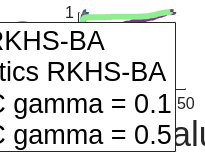

xlabel('x: Error Value', 'FontSize', 18);
ylabel('F(x)', 'FontSize', 18);

title("")
grid off


yticks([0 0.25 0.5 0.75 1])
% title(title_string)
hold off


%% LineStyle

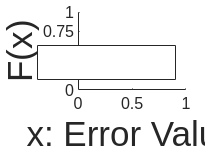

cla

rootfolder = '../../exp/';
use_icp = false

use_icp = logical
   0


gtfilename_cvo = append(rootfolder,'cvo_error_list.txt');
error_cvo = readmatrix(gtfilename_cvo);
gtfilename_cvosem = append(rootfolder,'cvosem_error_list.txt');
error_cvosem = readmatrix(gtfilename_cvosem);
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc);
if use_icp==true
    gtfilename_icp = append(rootfolder,'icp_error_list.txt');
    error_icp = readmatrix(gtfilename_icp);
end
title_string = "total tartanair";
figure
hold on

ax1 = cdfplot(error_cvo)

ax1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.5162 0.5162 0.5366 0.5366 0.5490 0.5490 0.5734 0.5734 0.5744 0.5744 0.5816 0.5816 0.6105 0.6105 0.6123 0.6123 0.6311 0.6311 0.6544 0.6544 0.6667 0.6667 0.6921 0.6921 0.6983 0.6983 0.6986 0.6986 0.7125 0.7125 0.7213 0.7213 … ]
              YData: [0 0 0.0013 0.0013 0.0025 0.0025 0.0037 0.0037 0.0050 0.0050 0.0063 0.0063 0.0075 0.0075 0.0088 0.0088 0.0100 0.0100 0.0112 0.0112 0.0125 0.0125 0.0138 0.0138 0.0150 0.0150 0.0163 0.0163 0.0175 0.0175 0.0187 0.0187 0.0200 0.0200 … ]

  Show 



if use_icp==true
    cdfplot(error_cvosem)
    cdfplot(error_icp)
    cdfplot(error_jrmpc)
    legend(["RKHS: Color only","RKHS: Semantic + Color","Colored-ICP","JRMPC"],'Location','southeast')
else
    ax2 = cdfplot(error_jrmpc)
    set( ax1, 'LineWidth', 3,'Color', [0.8500 0.3250 0.0980]);
    set( ax2, 'LineWidth', 3,'Color', [0.4940 0.1840 0.5560]);
    ax3 = cdfplot(error_jrmpc_large)
    set( ax3, 'LineWidth', 3,'Color', [144/255 238/255 144/255]);
    legend(["RKHS-BA","JRMPC gamma = 0.1","JRMPC gamma = 0.5"],'NumColumns',1,'Location','southeast','FontSize', 14)
    
end

ax2 =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.4245 0.4245 0.5667 0.5667 0.5767 0.5767 0.5937 0.5937 0.6093 0.6093 0.6431 0.6431 0.6531 0.6531 0.6637 0.6637 0.6705 0.6705 0.6705 0.6705 0.7043 0.7043 0.7103 0.7103 0.7151 0.7151 0.7172 0.7172 0.7227 0.7227 0.7232 0.7232 … ]
              YData: [0 0 0.0013 0.0013 0.0025 0.0025 0.0037 0.0037 0.0050 0.0050 0.0063 0.0063 0.0075 0.0075 0.0088 0.0088 0.0100 0.0100 0.0112 0.0112 0.0125 0.0125 0.0138 0.0138 0.0150 0.0150 0.0163 0.0163 0.0175 0.0175 0.0187 0.0187 0.0200 0.0200 … ]

  Show 

ax3 =   Line with properties:

              Color: [0.5647 0.9333 0.5647]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.1870 0.1870 0.2156 0.2156 0.2263 0.2263 0.2476 0.2476 0.2674 0.2674 0.2692 0.2692 0.2712 0.2712 0.2805 0.2805 0.2812 0.2812 0.2857 0.2857 0.2916 0.2916 0.2920 0.2920 0.2971 0.2971 0.3050 0.3050 0.3124 0.3124 0.3206 0.3206 … ]
              YData: [0 0 0.0013 0.0013 0.0025 0.0025 0.0037 0.0037 0.0050 0.0050 0.0063 0.0063 0.0075 0.0075 0.0088 0.0088 0.0100 0.0100 0.0112 0.0112 0.0125 0.0125 0.0138 0.0138 0.0150 0.0150 0.0163 0.0163 0.0175 0.0175 0.0187 0.0187 0.0200 0.0200 … ]

  Show 

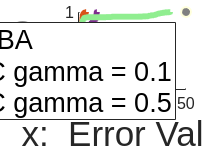

title("")
xlabel('x:  Error Value', 'FontSize', 18);
ylabel('F(x)', 'FontSize', 18);
yticks([0 0.25 0.5 0.75 1])
%xticks([0,2,4,6,8,10])
grid off
% a = get(gca,'XTickLabel');  
% title(title_string)
hold off


% 

## 0.5

claColor

Unrecognized function or variable 'claColor'.

rootfolder = '../../exp/tartanair_full_semantic/';
gtfilename_cvo = append(rootfolder,'cvo_error_list0.5.txt');
error_cvo = readmatrix(gtfilename_cvo)
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list0.5.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc)
hold on
cdfplot(error_cvo)
cdfplot(error_jrmpc)
legend(["rksh","jrmpc"],'Location','southeast')
title("0.5")
hold off

## 0.0

cla
rootfolder = '../../exp/tartanair_full_semantic/';
gtfilename_cvo = append(rootfolder,'cvo_error_list0.0.txt');
error_cvo = readmatrix(gtfilename_cvo);
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list0.0.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc);
hold on
cdfplot(error_cvo)
cdfplot(error_jrmpc)
legend(["rksh","jrmpc"])
title("0.0")
hold off

## 0.125

cla
rootfolder = '../../exp/tartanair_full_semantic/';
gtfilename_cvo = append(rootfolder,'cvo_error_list0.125.txt');
error_cvo = readmatrix(gtfilename_cvo);
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list0.125.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc);
hold on
cdfplot(error_cvo)
cdfplot(error_jrmpc)
title("0.125")
legend(["rksh","jrmpc"])
hold off